# Evaluación 11.2 (Planeación de Trayectorias)

Alan Iván Flores Juárez | A01736001

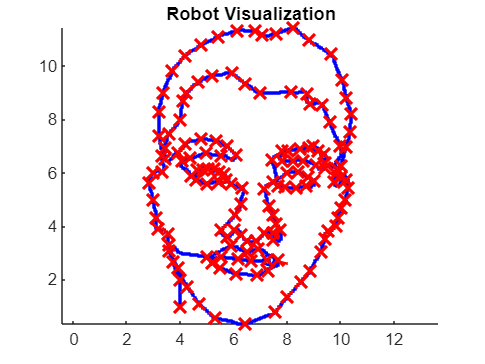

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:85;         % Time array

initPose = [4;1; pi/2];        % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4, 1;
4, 2;
3.7550224243231, 2.6702425940933;
3.574943736294, 3.3230278381987;
3.5411789822886, 3.7282048862641;
3.1697666882286, 3.9082835742931;
3.1247470162214, 4.3359704583622;
3, 5;
2.8433740661759, 5.6415409465729;
3, 6;
3.3273355402541, 6.0579729126401;
3.3385904582559, 6.6432286487346;
3.2260412782377, 7.3973081548563;
3.2035314422341, 8.2864466769998;
3.3723552122613, 9.0067614291161;
3.7212576703176, 9.8283704432487;
4.1939642263939, 10.3798614253377;
4.7904748804902, 10.7850384734031;
5.4094953705901, 11.100176177454;
6.15231995871, 11.3252745374903;
6.8051052028154, 11.3140196194885;
7.0864781528608, 11.1564507674631;
7.6042043809444, 11.2127253574722;
8.2232248710443, 11.4265687995067;
8.8309904431424, 10.9651171614322;
9.6638543752768, 10.4361360153468;
10.0690314233422, 9.4682130671906;
10.2378551933695, 8.8154278230852;
10.4066789633967, 8.1964073329853;
10.3729142093913, 7.5436220888799;
10.2266002753677, 6.9921311067909;
10.0352666693368, 6.2605614366728;
10, 7;
9.6075797852678, 7.9037794649381;
9.3374617532242, 8.5565647090434;
8.8647551971479, 8.5678196270452;
8.7634609351315, 8.950486839107;
8.178205199037, 9.0180163471179;
7, 9;
6.4449478267573, 9.3444089691706;
5.9497314346773, 9.7270761812324;
5.1843970105538, 9.6482917552196;
4.6779257004721, 9.3894286411779;
4.2277289803994, 9.0067614291161;
4.1039248823794, 8.6916237250652;
4, 8;
3.5861986542958, 7.4535827448654;
3.4286298022704, 6.9471114347836;
3.451139638274, 6.5081696327128;
3.946356030354, 6.7557778287528;
4.1939642263939, 7.0821704508054;
4.7792199624884, 7.2735040568363;
5.3419658625792, 7.1947196308236;
5.7583978286465, 7.0033860247927;
6.0847904506991, 6.6657384847382;
5.5332994686101, 6.6544835667364;
4.9818084865211, 6.7332679927491;
4.3965527504266, 6.5531893047201;
4.070160128374, 6.4406401247019;
4.4078076684285, 5.8891491426129;
4.8580043885011, 6.125502420651;
5.2744363545683, 6.1592671746565;
5.6458486486283, 5.9566786506238;
5.7358879926428, 5.7540901265911;
5.4657699605992, 5.6640507825765;
5.0043183225247, 5.6077761925675;
4.6103961924612, 5.7315802905874;
4.6554158644684, 6.1142475026492;
5.0605929125338, 6.1480122566547;
5.4657699605992, 6.0579729126401;
5.9159666806719, 5.6077761925675;
6.3211437287373, 5.450207340542;
6.2777117287405, 4.8545820906401;
6.0664171285378, 4.4183609805441;
5.5558093046138, 3.8632639022859;
5.7696527466483, 3.6156557062459;
6.0397707786919, 3.8632639022859;
6.27612405673, 3.671930296255;
6.52373225277, 3.4468319362186;
6.8501248748227, 3.4693417722223;
7.1427527428699, 3.7507147222677;
7.4691453649226, 3.7394598042659;
7.502910118928, 3.5031065262277;
7.7392633969662, 3.8632639022859;
7.6042043809444, 4.099617180324;
7.4691453649226, 4.4372647203785;
7.322831430899, 4.7636573424312;
7.1652625788735, 5.3939327505329;
7.502910118928, 5.6640507825765;
8, 6;
8.4370683130788, 6.0242081586347;
8.7859707711351, 5.8441294706056;
9.0110691311715, 5.7090704545838;
8.7409510991279, 5.5064819305511;
8.3470289690643, 5.4276975045384;
7.9193420849953, 5.4614622585438;
7.6829888069571, 5.5289917665547;
7.446635528919, 6.496914714711;
8.0318912650134, 6.8120524187618;
8.5158527390915, 6.9133466807782;
9, 7;
9.4049912612351, 6.6995032387437;
9.4387560152405, 6.2042868466637;
9.0785986391824, 6.3168360266819;
8.6284019191097, 6.4631499607055;
8.2232248710443, 6.4631499607055;
7.8180478229789, 6.4518950427037;
7.8401204702263, 6.8164790997439;
8.8432115959856, 6.9356582433985;
9.1709542410357, 6.836342290353;
9.4291757189539, 6.3794889063438;
9.866165912354, 6.1609938096438;
9.8463027217449, 5.9623619035528;
9.7668499593085, 5.6544824491118;
10.0350030325313, 5.8531143552028;
10.2038401527086, 5.7339352115482;
10.2932245104495, 5.4359873524118;
10.1839769620995, 4.9791339684026;
10.0350030325313, 4.7010492998753;
9.9158238888767, 4.3236486783025;
9.8463027217449, 4.025700819166;
9.5384232673039, 3.8270689130751;
9.4264192949186, 3.5253210831247;
9.2671071268482, 3.036005138337;
8.8802061472486, 2.3532387037495;
8.5388229299548, 1.920819961844;
8.0267481040142, 1.3632273735976;
7.5715704809558, 0.7942553447746;
6.43362642331, 0.3390777217163;
5.3070618062406, 0.5666665332455;
4.7153308962647, 1.1128796809155;
4.2715327137828, 1.7387489126207;
3.9187700559126, 2.4328947877847;
3.5887662791953, 3.0815229006428;
5.0225757918291, 2.8539340891136;
5.9101721567929, 3.2522145092897;
6.5132825073452, 3.0587640194899;
6.9343218086742, 3.161178984678;
7.673985446144, 2.7515191239255;
7.2984639071208, 2.3532387037495;
6.8774246057919, 2.1711676545261;
6.1150020871691, 2.2394442979849;
5.5005122960404, 2.4442742283611;
5.193267400476, 2.6377247181609;
5.5460300583462, 2.8539340891136;
6.1826383292102, 2.7681202991388;
6.6475697584769, 2.7085137056431;
7.2436356934343, 2.7323563430413;
];


% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.2;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 8;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

Se eligió por utilizar el código de Landmarks, ya que se encontró con actividades previas que era el código más sencillo y que a la vez mejores resultados arroja a la hora de trazar las coordenadas deseadas. Siendo la única complicación encontrar las coordenadas, ya que estas fueron trazadas con GeoGebra, sin permitir exportar a ningún archivo fuera de gbb, por lo que también se escribió un código que extraiga dichas coordenadas y las guarde en un txt. faltando agregar únicamente el formato final para correr en MatLab.